# **Εργασία: Ειδικά Συστήματα Πλοίου**

Σχολή Ναυπηγών Μηχανολόγων Μηχανικών, ΕΜΠ

Αναστοπούλου Ευγενία-Συραϊνώ, nm20034

Καμιζούλης Χρήστος, nm20031

8ο εξάμηνο

## **Ερώτημα 1: **Ανάλυση των δεδομένων με τη χρήση διαφόρων γραφικών παραστάσεων

clear all
warning("off")
% load all data
Data2024 = readtable("Data2024.csv",'TrailingDelimitersRule','ignore')

Data2024 = 451228×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239               

% Extract the units
% Open the file for reading
fid = fopen('Data2024.csv', 'r');
% Read the header line and discard it
fgetl(fid);
% Read the next line as a string
second_line = fgetl(fid);
% Close the file
fclose(fid);
% Split the string into cell array of units
units = strsplit(second_line, '\t');
% Convert cell array to array
units = string(units);
% Initialize the fieldnames of the data
fieldnames = Data2024.Properties.VariableNames

fieldnames = 1×11 cell array
    {'Time'}    {'NOx'}    {'FuelConsumption'}    {'lambda'}    {'ExhaustGasMassFlow'}    {'IntakePressure'}    {'TorqueReference'}    {'Rot_Speed'}    {'EngineTorque'}    {'EGRCommand'}    {'ExhaustGasTemperature'}


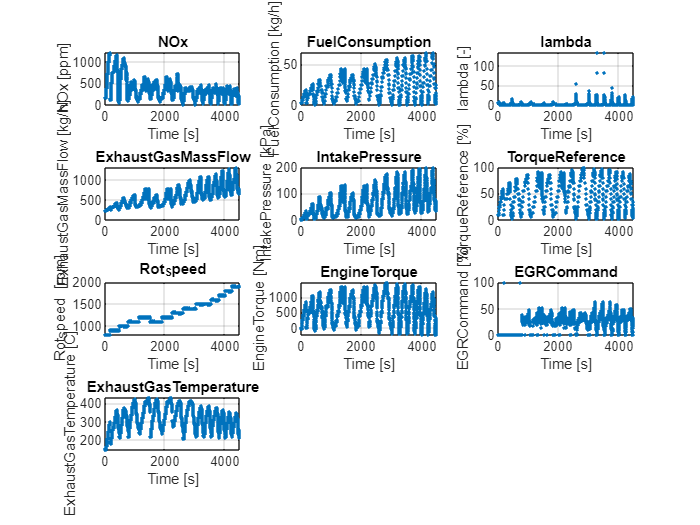

% Initialize a struct to store values
data = struct();

% Loop through each column
for i = 1:numel(fieldnames)
    % Extract values of the current column
    data.(fieldnames{i}) = table2array(Data2024(:, fieldnames{i}));
end

% Define the number of plots
num_plots = numel(fieldnames) - 1; % Excluding the first column

% Define the number of rows and columns for subplots
num_rows = ceil(sqrt(num_plots));
num_cols = ceil(num_plots / num_rows);

% Create a new figure
figure;

% Plot each column against the "Time" column on subplots
for i = 2:numel(fieldnames) % Start from the second column
    subplot(num_rows, num_cols, i-1); % Create subplot
    plot(data.Time, data.(fieldnames{i}),'.');
    title(fieldnames{i}); % Set title as column name
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Y-axis label
    grid on
end
hold off

clearvars fid second_line num_cols num_rows num_plots i ans

#### Ανάλυση Δεδομένων

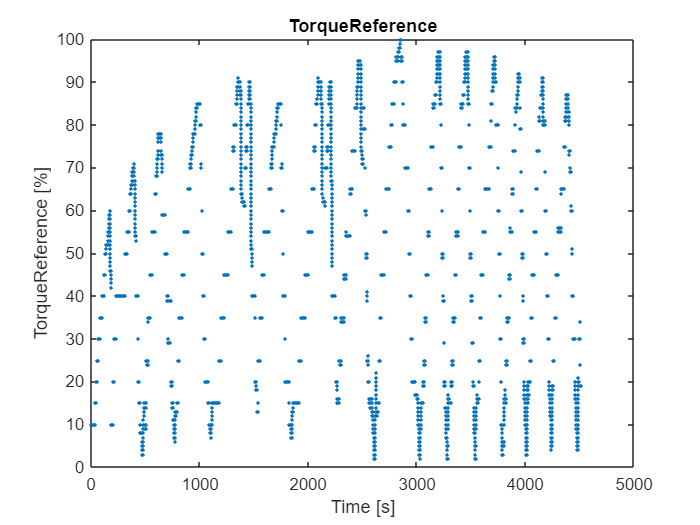

i = 7;
figure; % Create a new figure
plot(data.Time, data.(fieldnames{i}),".");
title(fieldnames{i}); % Set title as column name
xlabel('Time [s]'); % X-axis label

% Concatenate field name with unit and set it as Y-axis label
ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

clearvars i

**NOx:** Έχουν περιοδική κίνηση με απόσβεση, φθίνουσα. Περίοδος είναι 225s. Η μέση τιμή μικραίνει με την πάροδο του χρόνου, ξεκινάει από 600 ppm και καταλήγει εως και 200 ppm.

**Fuel Consumption:** Έχουν περιοδική κίνηση με αυξανόμενο πλάτος (ίδια περίοδος με ΝΟx 180-405s η πρώτη περίοδος). Οι μέγιστες τιμές ξεκινάνε από 20kg/h και φτάνουν ως 65kg/h.

**Λάμδα:** Έχει τιμές μικρότερες του 20 εως την στιγμή 2619s που γίνεται το πρώτο peak. Έχει συνολικά 8 peaks με τα μέγιστα να ξεπερνάνε την τιμή 130.

## Ερώτημα 2: Φιλτράρισμα και μετασχηματισμός των δεδομένων.

Χρησιμοποιήθηκαν συνολικά 3 φίλτρα. Το πρώτο που θα ασχοληθούμε θα είναι το Chauvenet. Το παρακάτω μπορεί να χρησιμοποιηθεί για να παράγουμε τα φιλτραρισμένα δεδομένα, επιλέγοντας κάθε φορά το σωστό threshold.

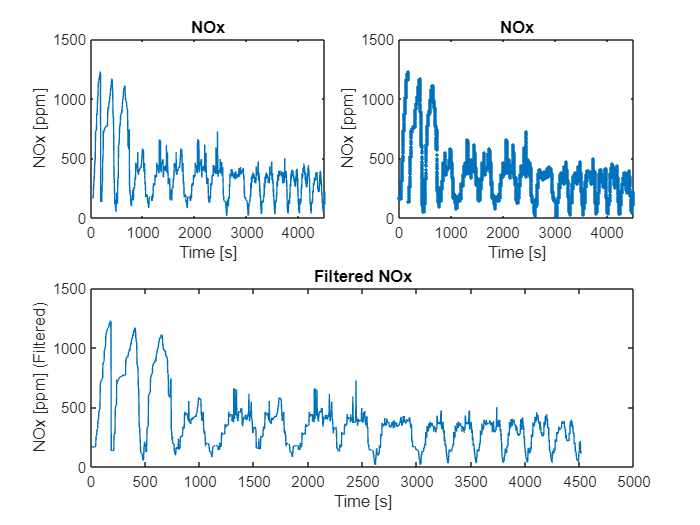

% Initialize a struct to store filtered values
data_filt = struct();
time_filt = struct();

% Store thresholds
thresholds = zeros(1,length(fieldnames));

clc

for j = 2:numel(fieldnames)
    [filteredData, filteredTime,threshold] = chauvenetFilter(Data2024,fieldnames,units,j);
    data_filt.(fieldnames{j}) = filteredData;
    time_filt.(fieldnames{j}) = filteredTime;
    thresholds(1,j) = threshold;
end

clearvars j threshold filteredData filteredTime

#### Αποθήκευση Φιλτραρισμένων Δεδομένων

Για να αναπαράγουμε τα παραπάνω δεδομένα θα αποθηκεύσουμε τα thresholds που παράγαμε και θα μπορούμε να φορτώνουμε ξανά τα παραπάνω δεδομένα.

% writematrix(thresholds,"thresholds.csv");
% clearvars ans 

#### Ανάκτηση Δεδομένων

Για να ξαναποκτήσουμε τα φιλτραρισμένα δεδομένα, μπορούμε να τρέξουμε τον παρακάτω κώδικα:

% Initialize a struct to store filtered values
data_filt = struct();
time_filt = struct();

% Read thresholds from the CSV file
thresholds = readmatrix('thresholds.csv');

for j = 2:numel(fieldnames)
    [filteredData, filteredTime, ~] = chauvenetFilter2(Data2024, fieldnames, units, j, thresholds(j));
    data_filt.(fieldnames{j}) = filteredData;
    time_filt.(fieldnames{j}) = filteredTime;
end


#### **Οπτικοποίηση Φιλτραρίσματος**

Με την παρακάτω εντολή, μπορούμε να συγκρίνουμε τα αποτελέσματα του φιλτραρίσματος που πραγματοποιήσαμε:

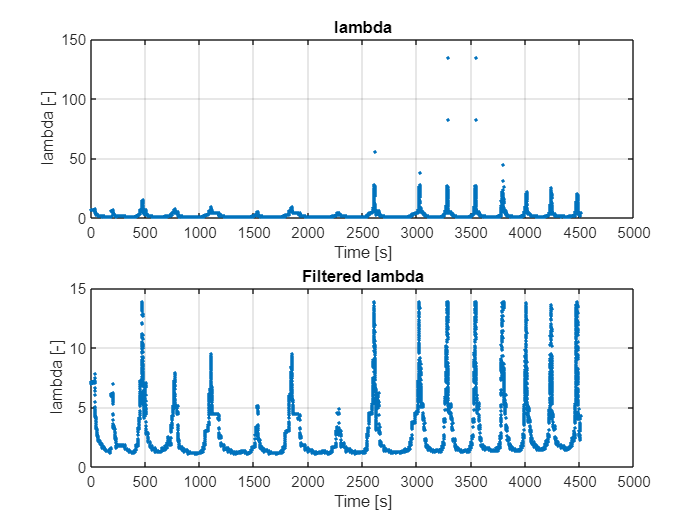

plot_differences(Data2024,fieldnames,units,data_filt,time_filt,4)

clearvars filteredData filteredTime j

Μέθοδος **Interquartile Range**:

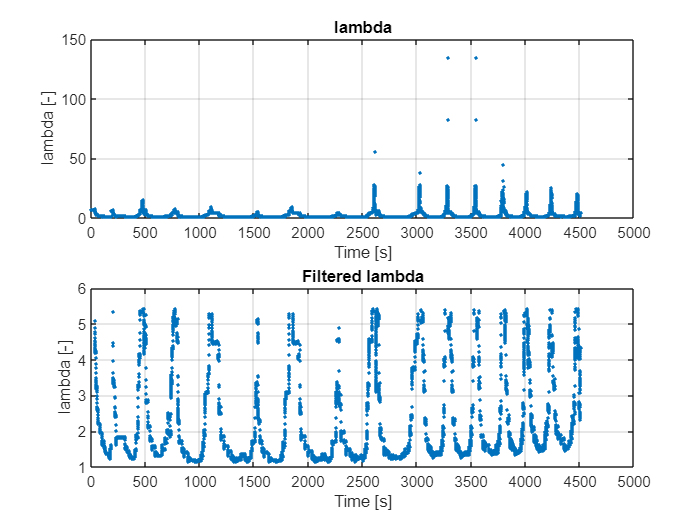

% Initialize a struct to store filtered values
data_filt = struct();
time_filt = struct();

for j = 2:numel(fieldnames)
    [filteredData,filteredTime] = IQR(Data2024.(fieldnames{j}),Data2024.Time);
    data_filt.(fieldnames{j}) = filteredData;
    time_filt.(fieldnames{j}) = filteredTime;
end 
plot_differences(Data2024,fieldnames,units,data_filt,time_filt,4)

clearvars filteredData filteredTime j

**Remove outliers using median:**

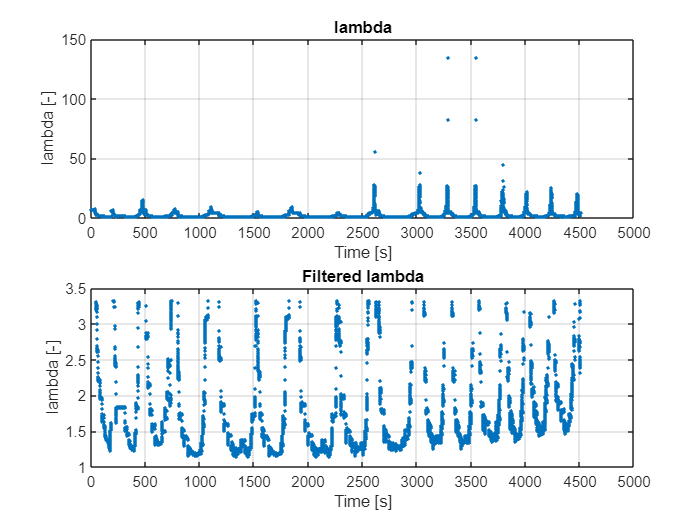

% Initialize a struct to store filtered values and corresponding times
data_filt = struct();
time_filt = struct();

for i = 2:numel(fieldnames)
    % Filter the data using rmoutliers
    [data_filt.(fieldnames{i}), idx] = rmoutliers(Data2024.(fieldnames{i}), "median");
    
    % Retain corresponding times using logical indexing
    time_filt.(fieldnames{i}) = Data2024.Time;
    time_filt.(fieldnames{i})(idx) = [];
end
plot_differences(Data2024,fieldnames,units,data_filt,time_filt,4)

clearvars i idx

**Τελικό φιλτράρισμα:**

Τελικά αποφασίσαμε να φιλτράρουμε τα δεδομένα σύμφωνα με τον παρακάτω τρόπο.

% Initialize a struct to store filtered values
data_filt = struct();
time_filt = struct();

% Read thresholds from the CSV file
thresholds = readmatrix('thresholds.csv');


% Create a copy of Data2024 to perform filtering on
filteredData2024 = Data2024;

for j = 2:numel(fieldnames)
    if j == 2 || j == 4 || j == 10
        [filteredData, filteredTime] = chauvenetFilter2(filteredData2024, fieldnames, units, j, thresholds(j));
        % Calculate removedIndices based on original and filtered data
        removedIndices = find(~ismember(filteredData2024.Time, filteredTime));
        data_filt.(fieldnames{j}) = filteredData;
        time_filt.(fieldnames{j}) = filteredTime;
        removedTimes = unique(filteredData2024.Time(removedIndices));
        time_filt.removed.(fieldnames{j}) = removedTimes;
        % Remove corresponding data
        filteredData2024(removedIndices,:) = [];
    elseif j == 3 || j == 6 || j == 7
        [filteredData, filteredTime] = IQR(filteredData2024.(fieldnames{j}), filteredData2024.Time);
        % Calculate removedIndices based on original and filtered data
        removedIndices = find(~ismember(filteredData2024.Time, filteredTime));
        data_filt.(fieldnames{j}) = filteredData;
        time_filt.(fieldnames{j}) = filteredTime;
        removedTimes = unique(filteredData2024.Time(removedIndices));
        time_filt.removed.(fieldnames{j}) = removedTimes;
        % Remove corresponding data
        filteredData2024(removedIndices,:) = [];
    elseif j == 5 || j == 8 || j == 9 || j == 11
        % Filter the data using rmoutliers
        [data_filt.(fieldnames{j}), idx] = rmoutliers(filteredData2024.(fieldnames{j}), "median");
        % Retain corresponding times using logical indexing
        time_filt.(fieldnames{j}) = filteredData2024.Time;
        removedIndices = idx;
        removedTimes = unique(filteredData2024.Time(removedIndices));
        time_filt.removed.(fieldnames{j}) = removedTimes;
        % Remove corresponding data
        filteredData2024(removedIndices,:) = [];
    end
end

filteredData2024

filteredData2024 = 440726×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239       

clearvars data_filt filteredData filteredTime idx j removedIndices removedTimes thresholds time_filt data

### Χωρισμός Δεδομένων:

% Initialize structs to store training and testing data
training = struct();
testing = struct();

for i = 1:numel(fieldnames)
    % Define the percentage of data for training and testing
    train_percent = 0.8;
    test_percent = 1 - train_percent;

    % Get the field name
    fieldname = fieldnames{i};

    % Extract the data directly from Data2024
    data2 = filteredData2024.(fieldname);
    times2 = filteredData2024.Time;

    % Create indices for random partition with 75% training and 25% testing
    cv = cvpartition(size(data2, 1), 'Holdout', test_percent);

    % Get indices for training and testing sets
    train_idx = cv.training;
    test_idx = cv.test;

    % Split the data into training and testing sets
    training.(fieldname) = data2(train_idx, :);
    testing.(fieldname) = data2(test_idx, :);
end
training

training = struct with fields:
                     Time: [352581×1 double]
                      NOx: [352581×1 double]
          FuelConsumption: [352581×1 double]
                   lambda: [352581×1 double]
       ExhaustGasMassFlow: [352581×1 double]
           IntakePressure: [352581×1 double]
          TorqueReference: [352581×1 double]
                Rot_Speed: [352581×1 double]
             EngineTorque: [352581×1 double]
               EGRCommand: [352581×1 double]
    ExhaustGasTemperature: [352581×1 double]


testing

testing = struct with fields:
                     Time: [88145×1 double]
                      NOx: [88145×1 double]
          FuelConsumption: [88145×1 double]
                   lambda: [88145×1 double]
       ExhaustGasMassFlow: [88145×1 double]
           IntakePressure: [88145×1 double]
          TorqueReference: [88145×1 double]
                Rot_Speed: [88145×1 double]
             EngineTorque: [88145×1 double]
               EGRCommand: [88145×1 double]
    ExhaustGasTemperature: [88145×1 double]


% % Define file paths for saving
% training_file = 'training_data-normalized.mat';  % Specify the file path for saving training data
% testing_file = 'testing_data-normalized.mat';    % Specify the file path for saving testing data
% 
% % Save training and testing structs to files
% save(training_file, 'training');
% save(testing_file, 'testing');

% Initialize structs to store training and validating data
training2 = struct();
validating = struct();

for i = 1:numel(fieldnames)
    % Define the percentage of data for training and testing
    train_percent = 0.8;
    val_percent = 1 - train_percent;

    % Get the field name
    fieldname = fieldnames{i};

    % Extract the data and corresponding times corresponding to the field name
    data2 = training.(fieldname);
    times2 = training.Time;

    % Create indices for cross-validation with 80% training and 20% testing
    cv = cvpartition(size(data2, 1), 'Holdout', val_percent);

    % Get indices for training and testing sets
    train_idx = cv.training;
    val_idx = cv.test;

    % Split the data into training and testing sets
    training2.(fieldname) = data2(train_idx, :);
    validating.(fieldname) = data2(val_idx, :);
end
training2

training2 = struct with fields:
                     Time: [282065×1 double]
                      NOx: [282065×1 double]
          FuelConsumption: [282065×1 double]
                   lambda: [282065×1 double]
       ExhaustGasMassFlow: [282065×1 double]
           IntakePressure: [282065×1 double]
          TorqueReference: [282065×1 double]
                Rot_Speed: [282065×1 double]
             EngineTorque: [282065×1 double]
               EGRCommand: [282065×1 double]
    ExhaustGasTemperature: [282065×1 double]


validating

validating = struct with fields:
                     Time: [70516×1 double]
                      NOx: [70516×1 double]
          FuelConsumption: [70516×1 double]
                   lambda: [70516×1 double]
       ExhaustGasMassFlow: [70516×1 double]
           IntakePressure: [70516×1 double]
          TorqueReference: [70516×1 double]
                Rot_Speed: [70516×1 double]
             EngineTorque: [70516×1 double]
               EGRCommand: [70516×1 double]
    ExhaustGasTemperature: [70516×1 double]


% % Define file paths for saving
% training_file = 'training2_data-normalized.mat';  % Specify the file path for saving training data
% validating_file = 'validating_data-normalized.mat';    % Specify the file path for saving testing data
% 
% % Save training and validating structs to files
% save(training_file, 'training2');
% save(validating_file, 'validating');
clearvars cv data2 fieldname i test_idx test_percent times2 train_idx train_percent training validx val_percent

**Load previewsly made training and testing data:**

% Load previewsly filtered Data
filtered_data = load("separated_data\filtered_data.mat");
filtered_data = filtered_data.Data2024

filtered_data = 440726×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239          

% Load the training data from the .mat file
training = load('separated_data\training2_data.mat');
training = struct2table(training.training2)

training = 282065×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6           7.158            239               

% Load the testing data from the .mat file
testing = load('separated_data\testing_data.mat');
testing = struct2table(testing.testing)

testing = 88145×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

    0.08    167.5          2.6           7.158            239                 4                 10            800.51         3.8323           0                152.31        
    0.14    167.5          2.6          7.1676          239.8                 

% Load the validating data from the .mat file
validating = load('separated_data\validating_data.mat');
validating = struct2table(validating.validating)

validating = 70516×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

    0.02    167.5          2.6          7.1378          239.8                 4                 10            799.47          4.034           0                   152        
    0.03      167          2.6          7.1628          239.8              

#### Correlation Matrix

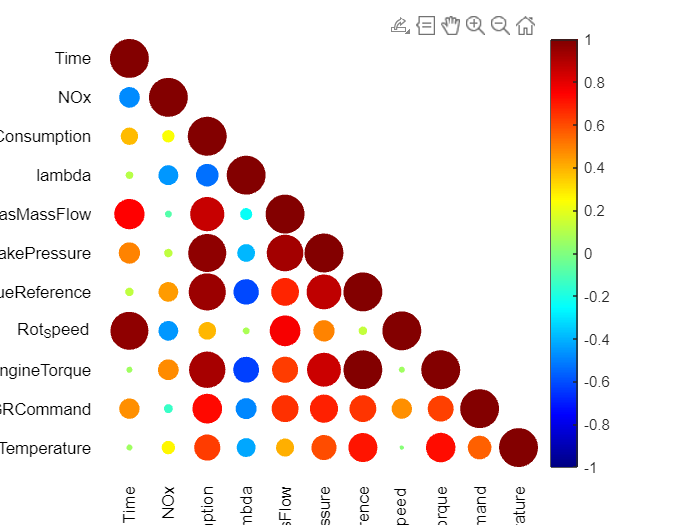

Corrcolormap(Data2024,fieldnames)

#### **Κανονικοποίηση Δεδομένων:**

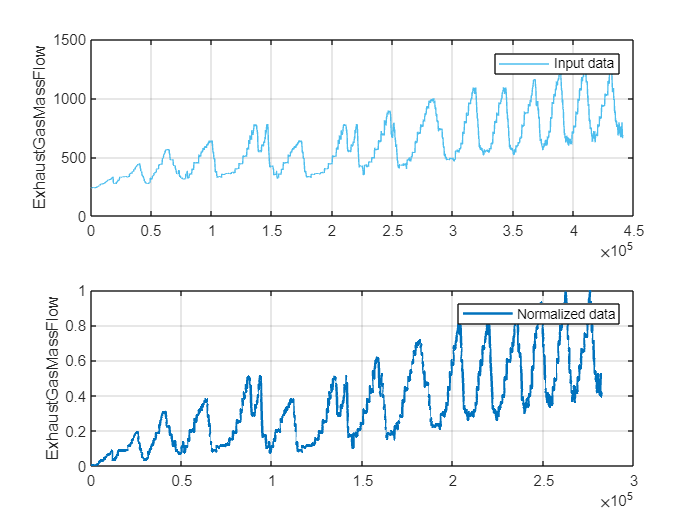

i = 5;
fieldname = fieldnames{i};
% Normalize Data
[normalizedTraining,centerValueTraining,scaleValueTraining] = normalize(training,"range");
[normalizedTesting,centerValueTesting,scaleValueTesting] = normalize(testing,"range");
[normalizedValidating,centerValueValidating,scaleValueValidating] = normalize(validating,"range");

% Display results
figure
tiledlayout(2,1);
nexttile
plot(filtered_data.(fieldnames{i}),"Color",[77 190 238]/255,"DisplayName","Input data")
legend
ylabel(fieldnames{i})
grid on

nexttile
plot(normalizedTraining.(fieldnames{i}),"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Normalized data")
legend
ylabel(fieldnames{i})
grid on

set(gcf,"NextPlot","New")
clearvars i fieldname

### Ερώτημα 4: Εκπαίδευση Νευρωνικού

Πρώτα πρέπει να μετατρέψουμε τα δεδομένα μας σε matrices

% Convert Engine Torque's test, train and validation sets from tables to matrices
input1_train = table2array(normalizedTraining(:,9));
input1_val = table2array(normalizedValidating(:,9));
input1_test = table2array(normalizedTesting(:,9));

% Convert NOx's test, train and validation sets from tables to matrices
NOx_train = table2array(normalizedTraining(:,2));
NOx_val =  table2array(normalizedValidating(:,2));
NOx_test = table2array(normalizedTesting(:,2));

% Convert Intake Prssure's test, train and validation sets from tables to matrices
input2_train = table2array(normalizedTraining(:,6));
input2_val = table2array(normalizedValidating(:,6));
input2_test = table2array(normalizedTesting(:,6));

% Convert Fuel Consumption's test, train and validation sets from tables to matrices
Fuel_Consumption_train = table2array(normalizedTraining(:,2));
Fuel_Consumption_val =  table2array(normalizedValidating(:,2));
Fuel_Consumption_test = table2array(normalizedTesting(:,2));

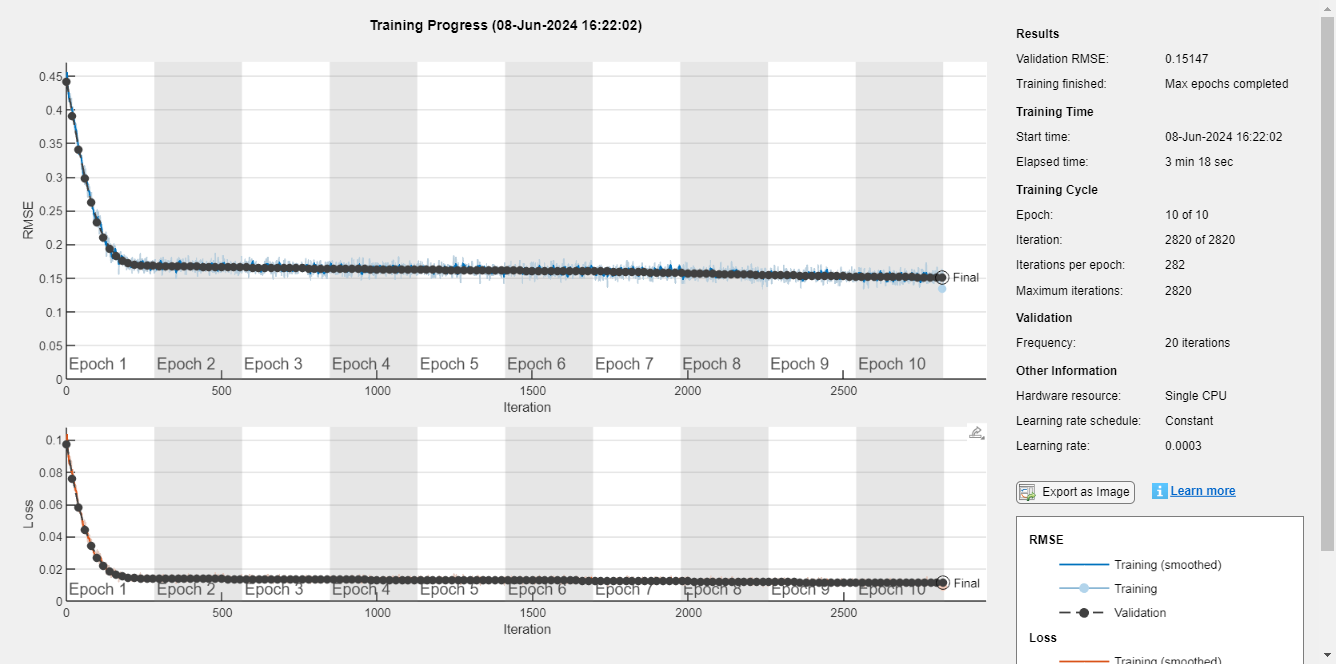

% Input NOx network's architecture as recommended
layers1 = [
    featureInputLayer(1)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

% Open DeepNetworkDesigner App
% deepNetworkDesigner

% Define training options 
options1 = trainingOptions('adam',...
    'Shuffle','every-epoch',...
    'MiniBatchSize',1000, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',3*1e-4, ...
    'ValidationData',{input1_val, NOx_val},...
    'Plots','training-progress', ...
    'ValidationFrequency',20,...
    'ValidationPatience',1,...
    'Verbose',false);


% Train 1st neural network to predict NOx emissions
NOx_net = trainNetwork(input1_train,NOx_train,layers1,options1);

### Ερώτημα 5: Αποτελέσματα

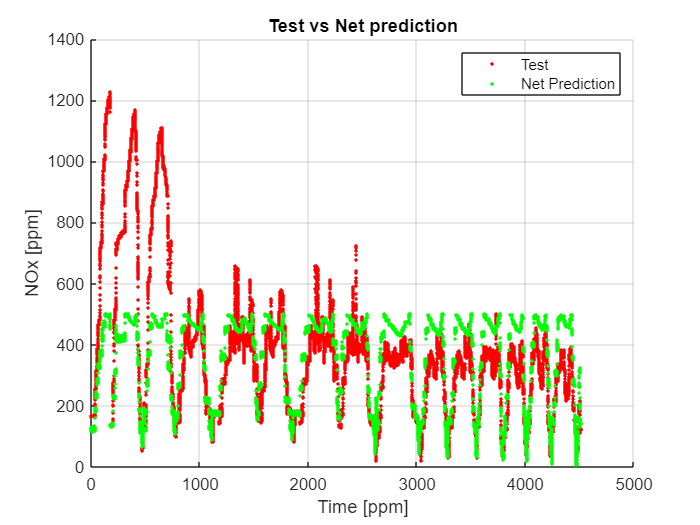

% Plot NOx emissions prediction using lambda's training, validation and test sets 
pred_and_plot2(normalizedTesting,NOx_net,1,2,9,fieldnames,units,centerValueTraining,scaleValueTraining)

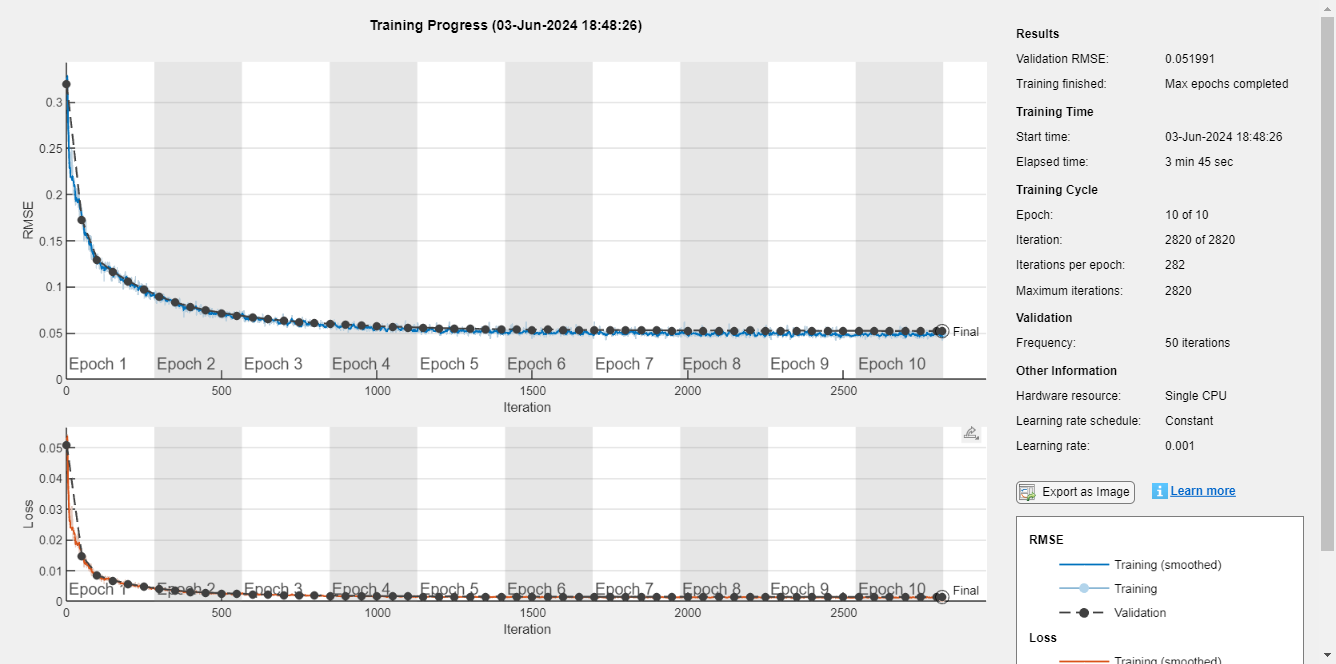

% Input Fuel Consumption network's architecture as recommended
layers2 = [
    featureInputLayer(1)
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

% Define training options 
options2 = trainingOptions('adam',...
    'Shuffle','every-epoch',...
    'MiniBatchSize',1000, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',3*1e-4, ...
    'ValidationData',{input2_val, Fuel_Consumption_val},...
    'Plots','training-progress', ...
    'Verbose',false);

% Train 2nd neural network to predict Fuel Consumption
Fuel_Consumption_net = trainNetwork(input2_train,Fuel_Consumption_train,layers2,options2);

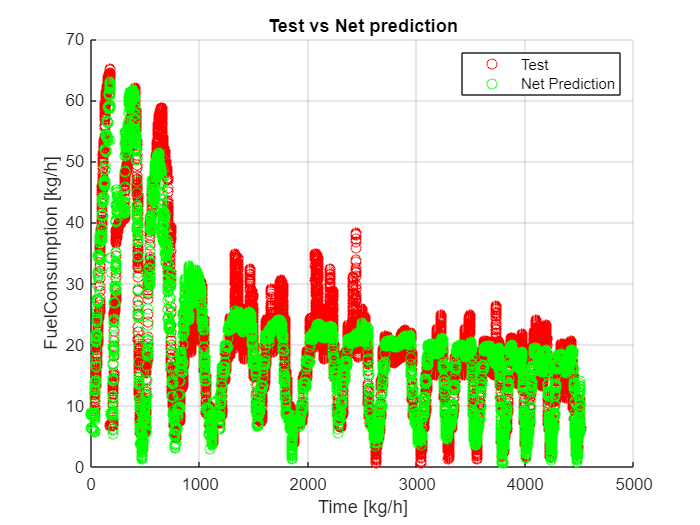

% Plot NOx emissions prediction using lambda's training, validation and test sets 
pred_and_plot2(input2_test,Fuel_Consumption_test,Fuel_Consumption_net,1,3,fieldnames,units,centerValueTesting,scaleValueTesting)

### Ερώτημα 6: Δημιουργία νέων παραμέτρων

Αρχικά, αντιστρέφουμε τον λόγο αέρα καυσίμου.

Data2024.lamda_reversed = 1./Data2024.lambda

Data2024 = 451228×14 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature    lamda_reversed     Power      ExhaustGasEnergy
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________    ______________    ________    ________________

       0    167.5          2.6          7.1378  

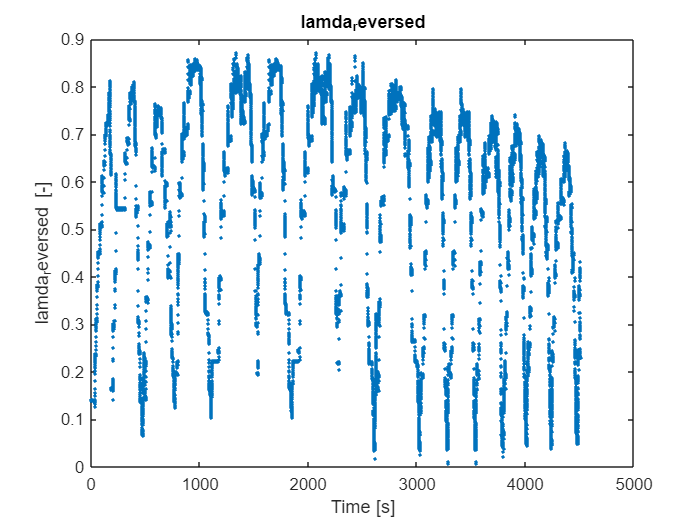

fieldnames{12}='lamda_reversed'; units{12} = '[-]';
i = 12;
figure; % Create a new figure
plot(Data2024.Time, Data2024.(fieldnames{i}),".");
title(fieldnames{i}); % Set title as column name
xlabel('Time [s]'); % X-axis label

% Concatenate field name with unit and set it as Y-axis label
ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

Βλέπουμε ότι τα δεδομένα δεν χρειάζονται κάποιο φίλτρο πια.

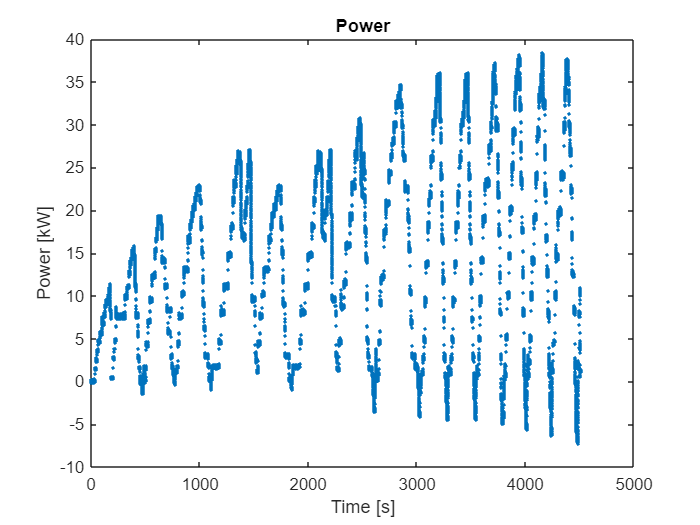

Data2024.Power = Data2024.EngineTorque.*Data2024.Rot_Speed / (60*1000);
fieldnames{13}='Power'; units{13} = '[kW]';
i = 13;
figure; % Create a new figure
plot(Data2024.Time, Data2024.(fieldnames{i}),".");
title(fieldnames{i}); % Set title as column name
xlabel('Time [s]'); % X-axis label

% Concatenate field name with unit and set it as Y-axis label
ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

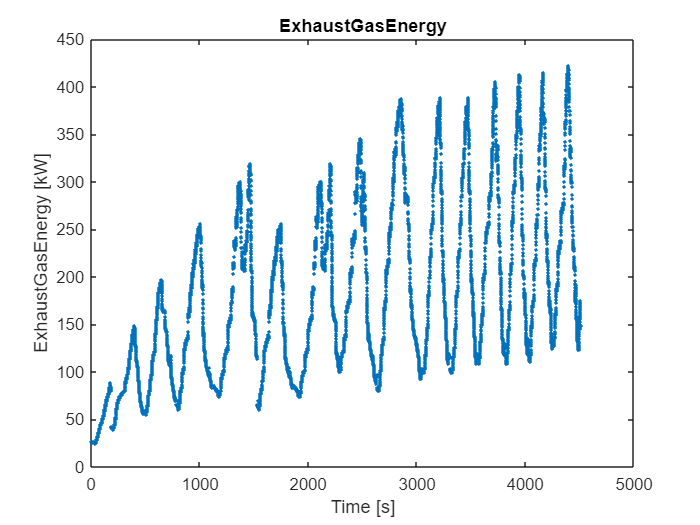

cp = 1.05;
Air_Temperature = 45;
Data2024.ExhaustGasEnergy = Data2024.ExhaustGasMassFlow*cp.*(Data2024.ExhaustGasTemperature-Air_Temperature) / 1000;
fieldnames{14}='ExhaustGasEnergy'; units{14} = '[kW]';
i = 14;
figure; % Create a new figure
plot(Data2024.Time, Data2024.(fieldnames{i}),".");
title(fieldnames{i}); % Set title as column name
xlabel('Time [s]'); % X-axis label

% Concatenate field name with unit and set it as Y-axis label
ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

clearvars i cp Air_Temperature

### Functions

Για την επιλογή των **thresholds**:

function [filteredData, filteredTime, threshold] = chauvenetFilter(Data, fieldnames, units, i)

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    redo = true;
    while redo
        % Calculate mean and standard deviation
        mu = mean(data);
        sigma = std(data);

        % Calculate residuals
        residuals = abs(data - mu);

        % Calculate probability
        p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
        p_mean = mean(p);
        
        % Plot unfiltered data
        figure;
        subplot(2,2,1); % Plot on the first row, first two columns
        plot(time, data);
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Plot unfiltered data
        subplot(2,2,2); % Plot on the second row, first column
        plot(time, data,".");
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Prompt user for threshold
        threshold = input(['Enter the threshold probability (mean is ', num2str(p_mean), '): ']);

        % Apply Chauvenet's Criterion (threshold probability)
        outliers = p < threshold;

        % Remove outliers
        filteredData = data(~outliers);
        filteredTime = time(~outliers);

        % Plot filtered data
        subplot(2,2,[3,4]); % Plot on the second row, second column
        plot(filteredTime, filteredData);
        title(['Filtered ', fieldnames{i}]); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s (Filtered)', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
        
        % Ask if the user wants to redo
        redo_prompt = input('Do you want to redo the filtering? (yes/no): ', 's');
        if strcmpi(redo_prompt, 'no')
            redo = false;
        end
    end
end

Για την **ανάκτηση** των φιλτραρισμένων δεδομένων:

function [filteredData, filteredTime, threshold] = chauvenetFilter2(Data, fieldnames, units, i, threshold)

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    % Calculate mean and standard deviation
    mu = mean(data);
    sigma = std(data);

    % Calculate residuals
    residuals = abs(data - mu);

    % Calculate probability
    p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
    p_mean = mean(p);

    % Apply Chauvenet's Criterion (threshold probability)
    outliers = p < threshold;

    % Remove outliers
    filteredData = data(~outliers);
    filteredTime = time(~outliers);
end

Μέθοδος **Interquartile Range**:

[https://www.indeed.com/career-advice/career-development/outliers-statistics](https://www.indeed.com/career-advice/career-development/outliers-statistics)

function [FilteredData,Time]=IQR(Data,Time)
%% Remove outliers from vectors with interquartile range method

% Sort Input Data in ascending order 
[Data,indx]=sort(Data);

% Calculate length of Vector Input Data 
n=length(Data);

% Check if the number of Data's elements is even or odd
if mod(n,2)~=0
    % If the number is odd, split the set as explained in the oddlength
    % function
    [~,Data1,Data3,n2]=oddlength(Data,n);
    % Check if the number of the split Datas' elements is even or odd
    if mod(n2,2)~=0
        % If the number is odd, calculate the median of each split set,
        % according to the oddlength function
        Q1=oddlength(Data1,n2);
        Q3=oddlength(Data3,n2);
    else
        % If the number is even, calculate the median of each split set,
        % according to the evenlength function
        Q1=evenlength(Data1,n2);
        Q3=evenlength(Data3,n2);
    end
else
    % If the number is even, split the set as explained in the evenlength
    % function
    [~,Data1,Data3,n2]=evenlength(Data,n);
    % Check if the number of the split Datas' elements is even or odd
    if mod(n2,2)~=0
        % If the number is odd, calculate the median of each split set,
        % according to the oddlength function
        Q1=oddlength(Data1,n2);
        Q3=oddlength(Data3,n2);
    else
        % If the number is even, calculate the median of each split set,
        % according to the evenlength function
        Q1=evenlength(Data1,n2);
        Q3=evenlength(Data3,n2);
    end
end

% Calculate the value of IQR
vIQR=Q3-Q1;

% Unsort the Data
UData(indx)=Data;

% Transpose the Unsorted Data matrix
UData=transpose(UData);

% Delete the values that are outside the IQR range
idx=UData>=Q3+1.5*vIQR | UData<=Q1-1.5*vIQR;
UData(idx)=[];
Time(idx)=[];

% Save the filtered Data
FilteredData=UData;
end
function [Median,LowerSet,UpperSet,n2]=oddlength(Data,n)
%% This function calculates the Median of the Input Vector Data set, 
%% divides the set to Upper and Lower halves and calculates the length of the produced sets
%% when the number of elements is odd

% The median of an odd set is the element that divides the set into two
% sets with an equal number of elements
Median=Data((n-1)/2+1);

% The lower half of the set contains elements from the first one to the one before
% the median of the original set
LowerSet=Data(1:(n-1)/2);

% The upper half of the set contains elements from the one after
% the median to the end of the original set
UpperSet=Data((n-1)/2+2:end);

% Calculate the length of the produced sets
n2=length(LowerSet);
end
function [Median,LowerSet,UpperSet,n2]=evenlength(Data,n)
%% This function calculates the Median of the Input Vector Data set, 
%% divides the set to Upper and Lower halves and calculates the length of the produced sets
%% when the number of elements is even

% The median of an even set is the mean value of the two central elements
% that split the set to two sets with an equal number of elements
Median=(Data(n/2)+Data(n/2+1))/2;

% The lower half of the set contains elements from the first one until the
% former central element of the original set
LowerSet=Data(1:n/2);

% The upper half of the set contains elements from the first latter central element 
% until the end of the original set
UpperSet=Data(n/2+1:end);

% Calculate the length of the produced sets
n2=length(UpperSet);
end


**To plot data filtered and unfiltered:**

function plot_differences(Data2024,fieldnames,units,data_filt,time_filt,i)
    % Plot unfiltered data
    figure;
    subplot(2,1,1); % Plot on the first row, first two columns
    plot(Data2024.Time, Data2024.(fieldnames{i}),".");
    title(fieldnames{i}); % Set title as column name
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
    grid on
    
    % Plot unfiltered data
    subplot(2,1,2); % Plot on the second row, first column
    plot(time_filt.(fieldnames{i}),data_filt.(fieldnames{i}),".");
    title(['Filtered ' fieldnames{i}]);
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
    grid on
end

function [] = pred_and_plot(x,y,net,i,j,fieldnames)
    preds = predict(net,x);
    figure
    x=x(:,i);
    scatter(x,y,'r')
    hold on
    hold on
    scatter(x,preds,'g')
    title('Test vs Net prediction')
    ylabel(sprintf('%s', fieldnames{j}));
    xlabel(sprintf('%s', fieldnames{i}));
    legend('Test','Net Prediction')
    grid on
end

function [] = pred_and_plot2(normalizedTesting,net,i,j,k,fieldnames,units,centerValueTraining,scaleValueTraining)
    x = table2array(normalizedTesting(:,i));
    y = table2array(normalizedTesting(:,j));
    z = table2array(normalizedTesting(:,k));
    preds = predict(net,z);
    figure
    x = x*scaleValueTraining{:,i}+centerValueTraining{:,i};
    y = y*scaleValueTraining{:,j}+centerValueTraining{:,j};
    preds = preds*scaleValueTraining{:,j}+centerValueTraining{:,j};
    scatter(x,y,'r.')
    hold on
    hold on
    scatter(x,preds,'g.')
    title('Test vs Net prediction')
    ylabel(sprintf('%s %s', fieldnames{j},units{j}));
    xlabel(sprintf('%s %s', fieldnames{i},units{j}));
    legend('Test','Net Prediction')
    grid on
end
